# E4

Threshold global (manual)

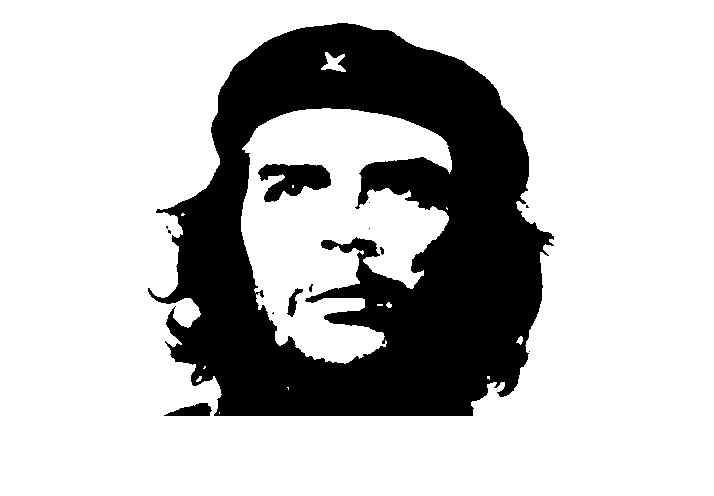

I = rgb2gray(imread('Che.jpg'));
BW = I > 95;
imshow(BW)

Binarització dos nivells

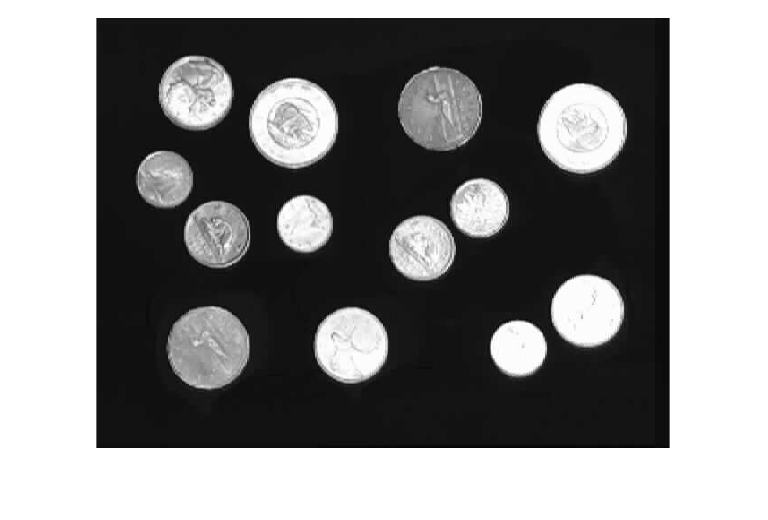

I = imread('money.tif');
imshow(I);

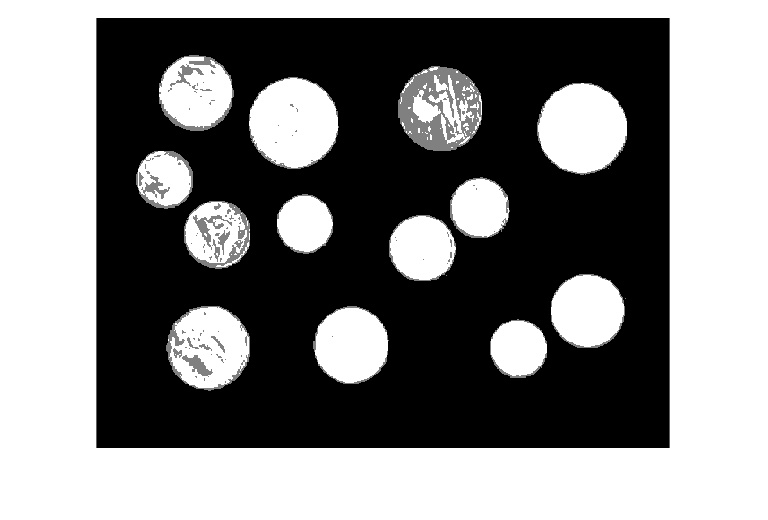


H = I > 150;
L = I < 50;
M = L == H; % a zero tant en L com en H

R = 2*H + M;
imshow(R,[])

Binarització per area

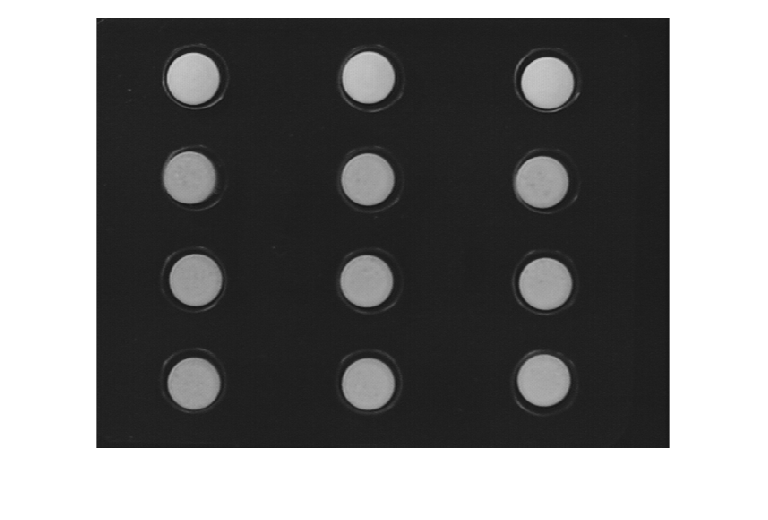

I = rgb2gray(imread('Blispac2.tif'));
imshow(I);

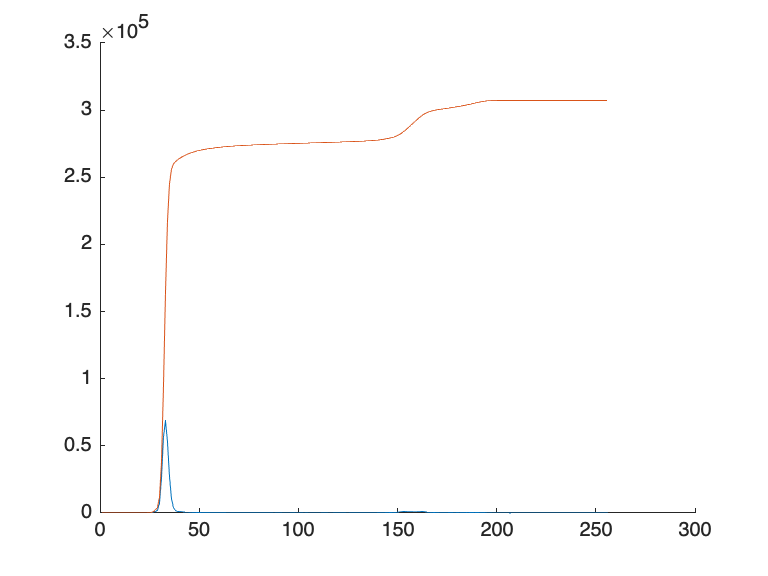

d = 95-38;
areapastilla = pi * (d/2)^2;
area = 12 * areapastilla;
h = imhist(I);
hacum = cumsum(h);
figure
hold on
plot(h)
plot(hacum)
hold off

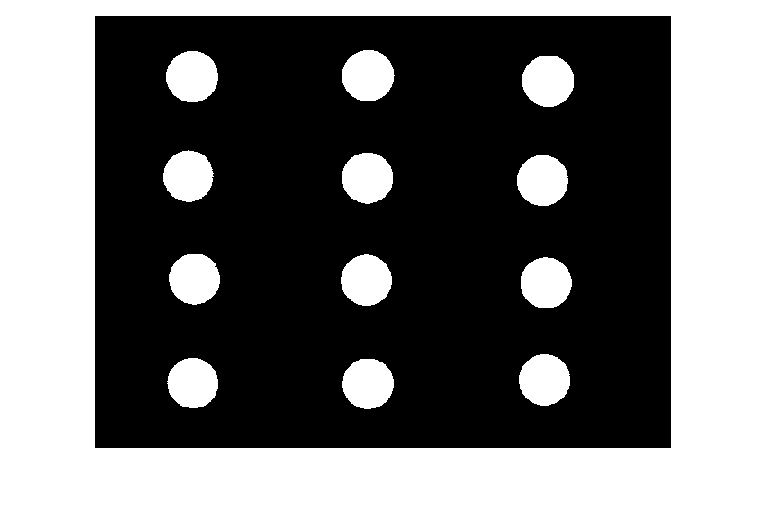

llindar1 = 0;

for i = 1:128
    if hacum(i) > area
        llindar1 = i;
    end
end
BW = I > llindar1;
imshow(BW);


[f,c] = size(I);
hb = hacum > (f*c-area);
llindar = find(hb, 1);
BW = I > llindar;
imshow(BW);

Otsu thresholding

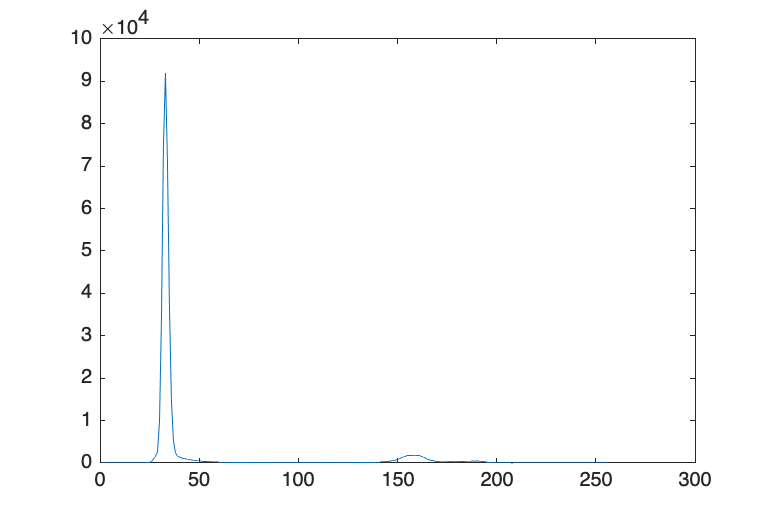

%level = 255 * otsuthresh(h);

[f, c] = size(I);
h = imhist(I);
p = h/f*c;
plot(p)

level = otsu(p)

level = 98

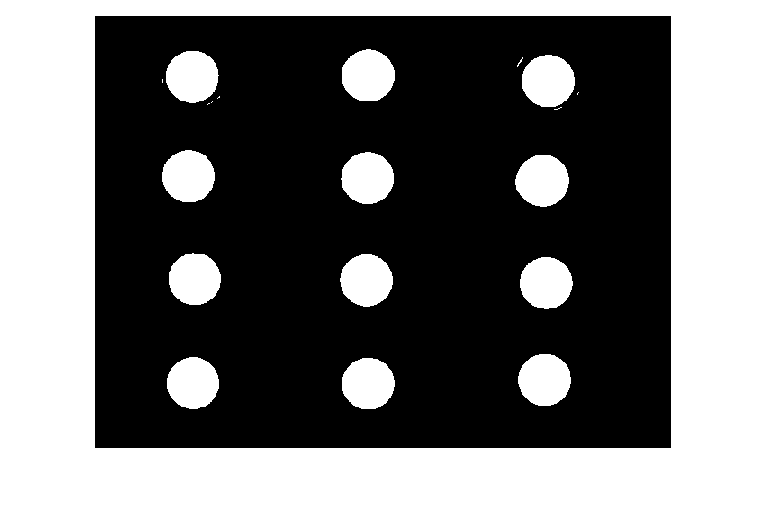

BW = I > level;
imshow(BW);

Labelling

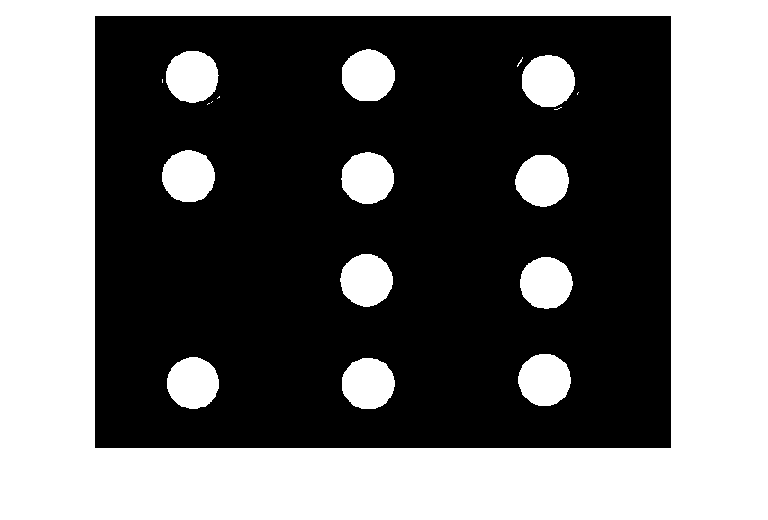

c = bwconncomp(BW);
CBW = BW;
CBW(c.PixelIdxList{5}) = 0;
imshow(CBW)

function level = otsu(histogramCounts)
total = sum(histogramCounts); % total number of pixels in the image 
%% OTSU automatic thresholding
top = 256;
sumB = 0;
wB = 0;
maximum = 0.0;
sum1 = dot(0:top-1, histogramCounts);
for ii = 1:top
    wF = total - wB;
    if wB > 0 && wF > 0
        mF = (sum1 - sumB) / wF;
        val = wB * wF * ((sumB / wB) - mF) * ((sumB / wB) - mF);
        if ( val >= maximum )
            level = ii;
            maximum = val;
        end
    end
    wB = wB + histogramCounts(ii);
    sumB = sumB + (ii-1) * histogramCounts(ii);
end
end